# **Extragerea informatiilor din harta de disparitate a imaginilor stereo**

## **Sisteme stereo vizuale**

- formate din doua sau mai multe camere aflate la o distanta una fata de cealalta

- desi capteaza imagini separat, aceste doua imagini sunt puse impreuna pentru a simula perceptia umana

- camerele au nevoie de calibrare printr-o serie de parametrii 

## **Parametrii intrinseci**

- **set de parametri**i pentru a face corespondenta dintre **coordonatele din planul imagine** si **planul camerei**

-     trebuie modificati separat pentru fiecare camera 

- **distanta focala f**

- **transformarile de la coordonatele imagine la coordonatele pixelilor**

- **distorsiunea geometrica optica**

                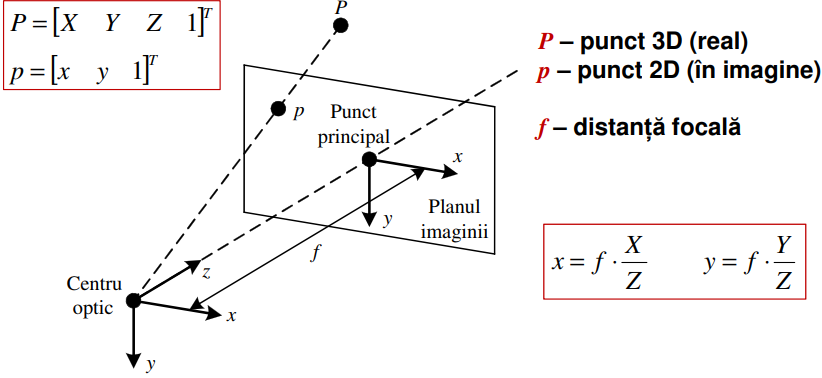

## Parametrii extrinseci

- **vector de translatie tridimensionala T -> **descrie pozitiile relative ale originilor cadrelor celor doua camere

- **matrice de rotatie R -> ** matrice ortogonala face ce face legatura dintre axele corespunzatoare celor doua cadre

               ** * matrice ortogonala -> inversa corespunde cu transpusa**

## **Disparitatea**

- **Disparitatea** reprezintă **diferențele** dintre **coordonatele orizontale** ale **aceluiași** **punct** în planul **imaginii** din **stânga** față de planul **imaginii** din **dreapta**

                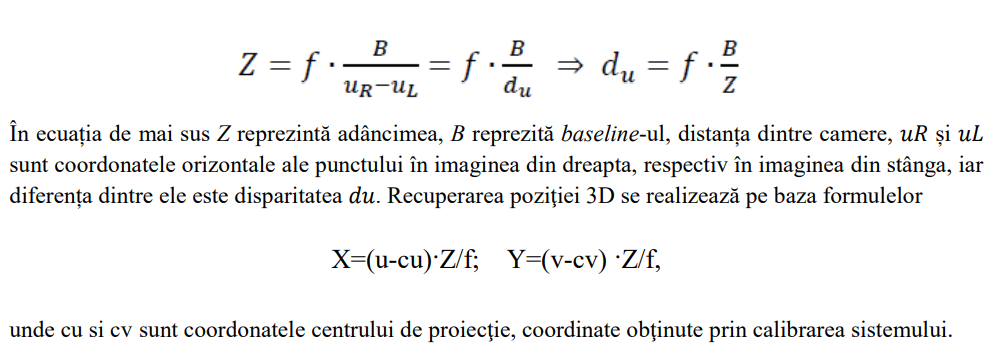

###   Block Matching - local method

    - construieste harta de disparitate folosind **suma diferentei absolute -> masoara diferentele dintre valorile intensitatilor pixelilor**

    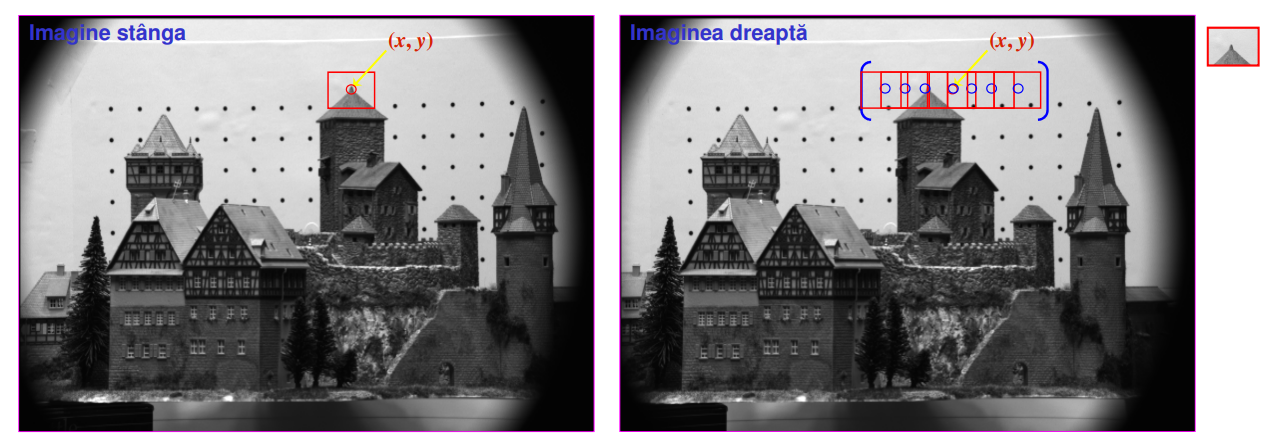

### Semi-Global Matching

    - ofera **harti de disparitate mai putin afectate de zgomot**, dar sunt **dificil de implementat** fara utilizarea unei **functii de cost** 

### Matlab functioning

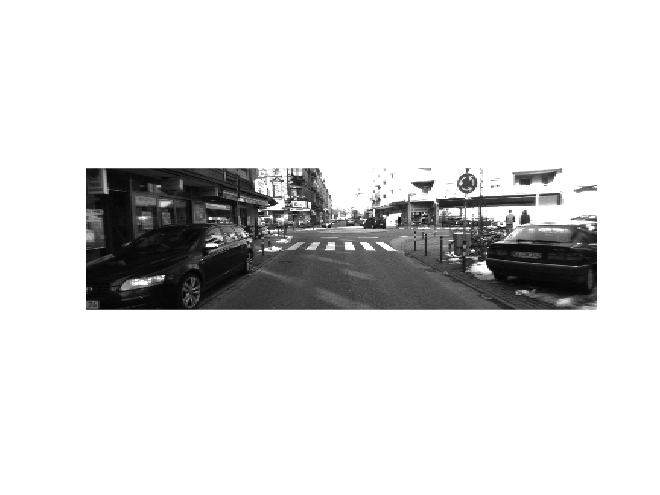

%% Matlab implementation
I1 = imread('L2_left.png');
I2 = imread('L2_right.png');

% afisare imagini initiale
figure; imshow(I1);

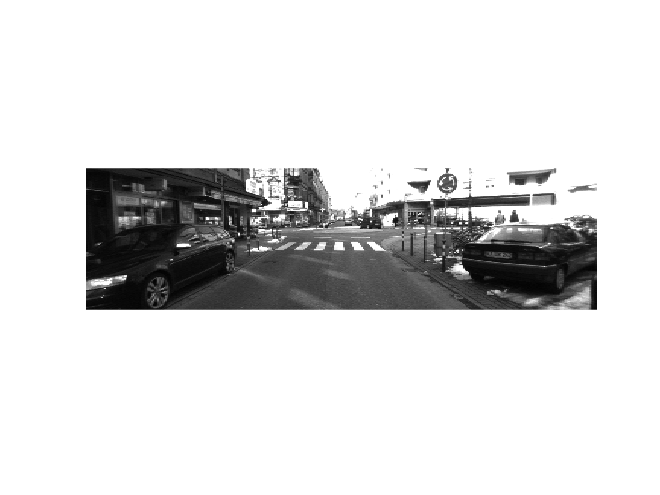

figure; imshow(I2);

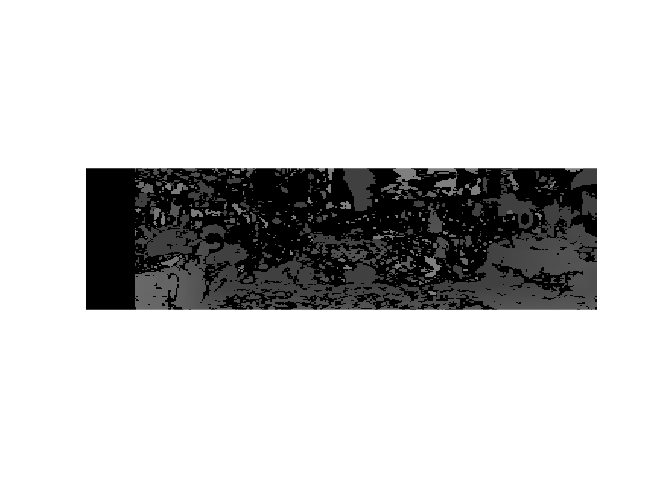


%calcul disparitate
disp1 = disparity(I1,I2,'Method','SemiGlobal','DisparityRange',[64 128]);
disp2 = disparity(I1,I2,'Method','BlockMatching');
disp3 = disparitySGM(I1,I2);

figure;imshow(uint8(disp1));

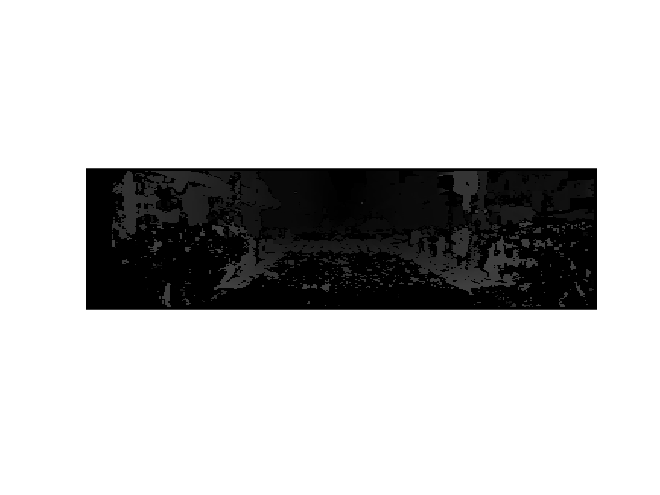

figure;imshow(uint8(disp2));

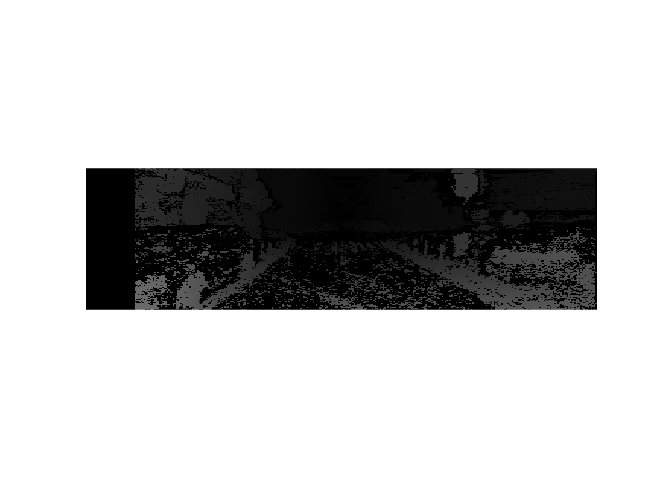

figure;imshow(uint8(disp3));

## Exercitiul 2

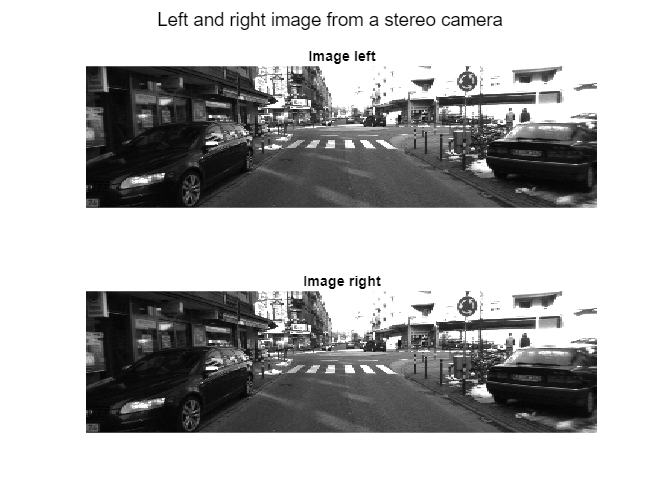

% parametrii necesari
f       = 647.2;   % distanta focala
cu      = 641.2;   % coordonata u a centrului de proiectie
cv      = 182.162; % coordonata v a centrului de proiectie
b       = 0.5787;  % baseline -> distanta dintre camere

% citire imagini 
I1 = imread('L2_left.png');
I2 = imread('L2_right.png');

% determinarea marimii uneia din imagini
[m,n] = size(I1);

% afisarea celor doua imagini in paralel
figure(1);
subplot(2,1,1)
imshow(I1);title('Image left');
subplot(2,1,2)
imshow(I1);title('Image right');
sgtitle("Left and right image from a stereo camera");

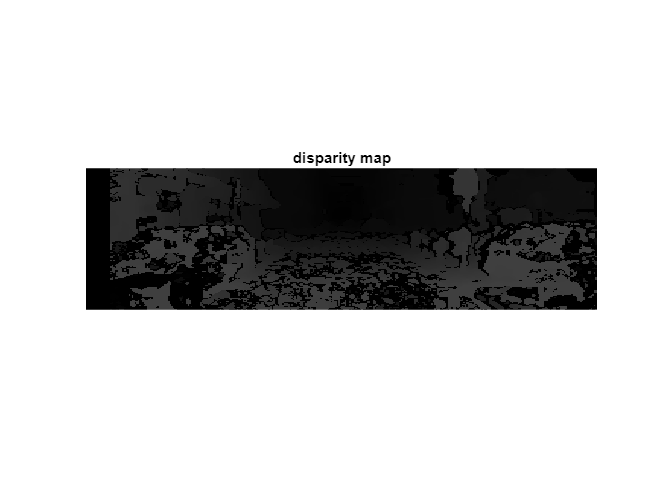


% calcul disparitate
disparity_map = disparity(I1,I2);


logical_map = disparity_map > 50 & disparity_map < 55; % imaginea A din document

% afisarea hartii de disparitate
figure(2)
imshow(uint8(disparity_map));title('disparity map');

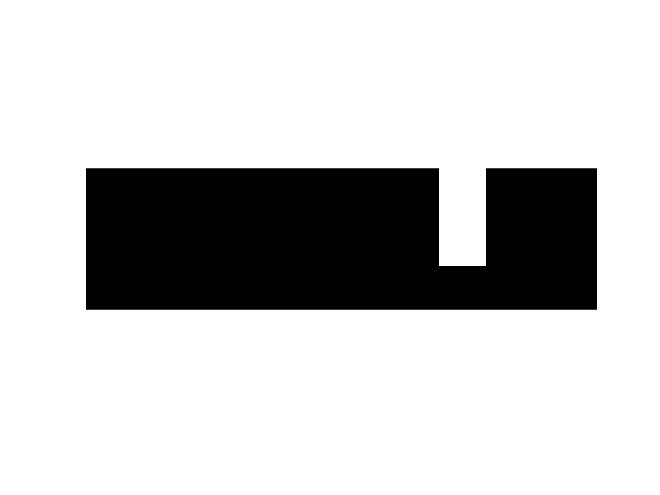


% determinarea mastii prin care ne concentram atentia doar pe semnul de
% circulatie
img_noua = zeros(m,n);
img_noua(1:257,928:1052) = 1;

% afisarea mastii
figure;imshow(img_noua); %imaginea B

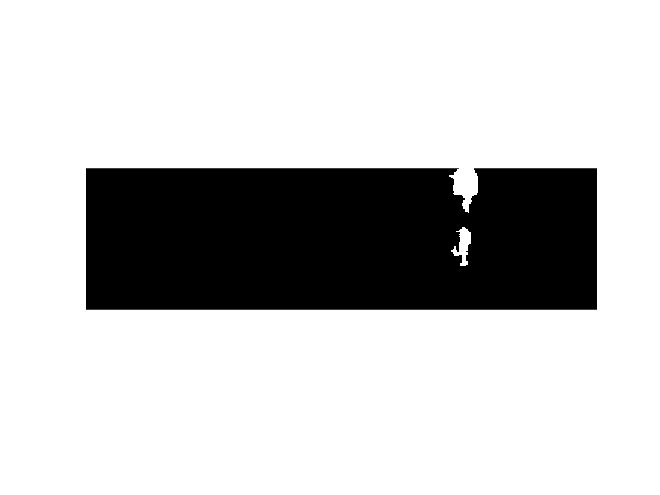


% suprarpunerea mastii peste imaginea initiala (operatia AND)
logical_map = logical_map .* img_noua;

% afisarea noii imagini
figure;imshow(logical_map);  %imaginea C


[r,c] = find(logical_map == 1);

v = repmat([1:m]',1,n);
u = repmat(1:n,m,1);

figure;
plot3(0,0,0,'*r');grid;hold on
for i = 1 : 15 : length(r)
    %nivelul de gri dintr o imagine = val_pixel din imagine/255;
    gray_level = double(I1(r(i),c(i)))/255;
    Z = f*b/disparity_map(r(i),c(i));
    X = ((u(r(i),c(i))-cu)*Z)/f;
    Y = ((v(r(i),c(i))-cv)*Z)/f;
%     X = (r(i)-cu)*Z/f;
%     Y = (c(i)-cv)*Z/f;
    
    plot3(X,Z, -Y,'.','Color',[gray_level gray_level gray_level]);
    % plot3(X,Y,Z);
    pause(0.001);
end